qin = pi

qin = 3.1416

qfin = 1.4805

qfin = 1.4805


vin = 0

vin = 0

vfin = -0.7185

vfin = -0.7185


syms T

[a, b, c, d] = cubic_poly_double_norm_compute_coeff(qin, qfin, vin, vfin, T, true);

##############################################################
Cubic Polynomial Double Normalized (tau belongs to [0, 1])

$$q\_tau = \mathrm{qin}+\mathrm{Dq}\,\left(a\,\tau^{3}+b\,\tau^{2}+c\,\tau +d\right)$$

Where Dq = (qfin - qin)---------------------------------------------------------
Equations:

$$eq\_1 = d=0$$

$$eq\_2 = a+b+c=1$$

$$eq\_3 = c=\frac{T\,\mathrm{vin}}{\mathrm{Dq}}$$

$$eq\_4 = 3\,a+2\,b+c=\frac{T\,\mathrm{vfin}}{\mathrm{Dq}}$$

---------------------------------------------------------
Symbolic solutions:

$$a = \frac{T\,\mathrm{vfin}-2\,\mathrm{Dq}+T\,\mathrm{vin}}{\mathrm{Dq}}$$

$$b = -\frac{T\,\mathrm{vfin}-3\,\mathrm{Dq}+2\,T\,\mathrm{vin}}{\mathrm{Dq}}$$

$$c = \frac{T\,\mathrm{vin}}{\mathrm{Dq}}$$

$$d = 0$$

---------------------------------------------------------
Numerical solutions:


$$a = \frac{404479541533212672\,T}{935112031966857625}-2$$

$$b = 3-\frac{404479541533212672\,T}{935112031966857625}$$

$$c = 0$$

$$d = 0$$

##############################################################


T = 2;
[a, b, c, d] = cubic_poly_double_norm_compute_coeff(qin, qfin, vin, vfin, T, false)

$$a = -\frac{1061264980867289906}{935112031966857625}$$

$$b = \frac{1996377012834147531}{935112031966857625}$$

$$c = 0$$

$$d = 0$$

double(a)

ans = -1.1349

double(b)

ans = 2.1349

double(c)

ans = 0

double(d)

ans = 0

syms t real
tau = t/T

$$tau = \frac{t}{2}$$

func = cubic_poly_double_norm(a, b, c, d, tau, qin, qfin)

$$func = \frac{530632490433644953\,t^{3}}{2251799813685248000}-\frac{1996377012834147531\,t^{2}}{2251799813685248000}+\pi$$

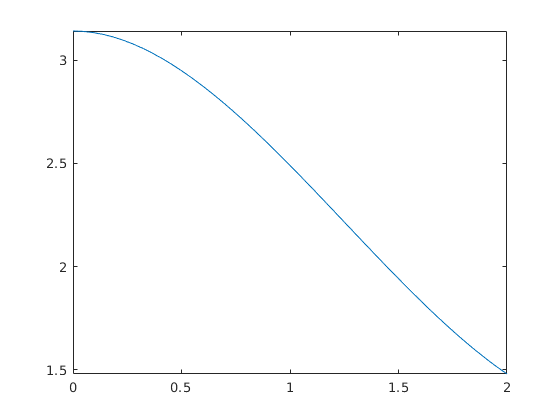

plot_function(func, t, [0, T])


subs(func, {t}, {0})

$$ans = \pi$$

double(subs(func, {t}, {T}))

ans = 1.4805